clear;
clc;

set( groot, 'defaultLineLineWidth', 1.2 ) ; % plot line 두께 지정
set( groot, 'defaultAxesXGrid', 'on' ) ; % x축 방향으로 grid 생성
set( groot, 'defaultAxesYGrid', 'on' ) ; % y축 방향으로 grid 생성
set( groot, 'defaultAxesTitleFontSizeMultiplier', 1.5);  % Title 크기 설정
set( groot, 'defaultAxesFontSize', 12 ); % 축에 있는 글씨 크기 지정
set( groot, 'defaultAxesFontName', 'Times New Roman'); % 축에 있는 글씨 폰트 지정
set( groot, 'defaultFigureColor', 'w'); % figure 색상

% Load Estimate target pose data
dateStr = '20250630';      % log date
runIdx  = '1';   % log nums

scriptFullPath = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(scriptFullPath);

while true
    [parentDir, folderName] = fileparts(currentDir);
    if strcmp(folderName, 'mppi_solver')
        projectRoot = currentDir;
        break;
    end
    if isempty(parentDir)
        error('Directory mppi_solver not found');
    end
    currentDir = parentDir;
end

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'mppi_canadarm');

ee_pose_1 = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/end_effector_pose');
pos_err_1 = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/pos_err');
ori_err_1 = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/ori_err');
cost_1 = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/cost');

clearvars dateStr runIdx scriptFullPath currentDir parentDir folderName projectRoot absPath

% Load Estimate target pose data
dateStr = '20250630';      % log date
runIdx  = '1';    % log nums

scriptFullPath = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(scriptFullPath);

while true
    [parentDir, folderName] = fileparts(currentDir);
    if strcmp(folderName, 'mppi_solver')
        projectRoot = currentDir;
        break;
    end
    if isempty(parentDir)
        error('Directory mppi_solver not found');
    end
    currentDir = parentDir;
end

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'mppi_canadarm');

ee_pose_2 = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/end_effector_pose');
pos_err_2 = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/pos_err');
ori_err_2 = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/ori_err');
cost_2 = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/cost');

clearvars dateStr runIdx scriptFullPath currentDir parentDir folderName projectRoot absPath

init_data_1_idx = 1;
ee_pose_1 = ee_pose_1(:,init_data_1_idx:end);
pos_err_1 = pos_err_1(:,init_data_1_idx:end);
ori_err_1 = ori_err_1(:,init_data_1_idx:end);
cost_1    = cost_1(:,init_data_1_idx:end);

init_data_2_idx = 1;
ee_pose_2 = ee_pose_2(:,init_data_2_idx:end);
pos_err_2 = pos_err_2(:,init_data_2_idx:end);
ori_err_2 = ori_err_2(:,init_data_2_idx:end);
cost_2    = cost_2(:,init_data_2_idx:end);

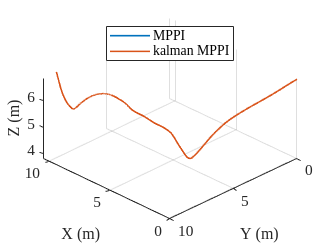

sim_time_ee_pose_1 = ee_pose_1(1,:);
ee_pos_1 = ee_pose_1(2:4,:);
ee_ori_1 = ee_pose_1(5:7,:);

sim_time_ee_pose_2 = ee_pose_2(1,:);
ee_pos_2 = ee_pose_2(2:4,:);
ee_ori_2 = ee_pose_2(5:7,:);

figure;
hold on
plot3(ee_pos_1(1,:), ee_pos_1(2,:), ee_pos_1(3,:))
plot3(ee_pos_2(1,:), ee_pos_2(2,:), ee_pos_2(3,:))
hold off
xlabel('X (m)', 'FontSize', 12);
ylabel('Y (m)', 'FontSize', 12);
zlabel('Z (m)', 'FontSize', 12);
% title("End Effector Pos")
legend("MPPI","kalman MPPI", "Location","best")
view([-1 1 1.5]);

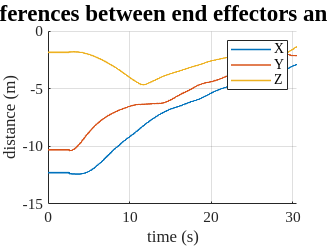

sim_time_pos_err_1 = pos_err_1(1,:);
sim_time_pos_err_2 = pos_err_2(1,:);
sim_time_pos_err_1 = sim_time_pos_err_1 - sim_time_pos_err_1(1);
sim_time_pos_err_2 = sim_time_pos_err_2 - sim_time_pos_err_2(1);

figure;
hold on
plot(sim_time_pos_err_1, pos_err_1(2,:));
plot(sim_time_pos_err_1, pos_err_1(3,:));
plot(sim_time_pos_err_1, pos_err_1(4,:));
hold off
title("Pos differences between end effectors and targets")
xlabel("time (s)")
ylabel("distance (m)")
legend("X","Y","Z")

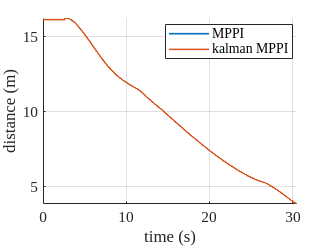


err_dist_1 = vecnorm(pos_err_1(2:4,:));
err_dist_2 = vecnorm(pos_err_2(2:4,:));

figure;
hold on
plot(sim_time_pos_err_1, err_dist_1);
plot(sim_time_pos_err_2, err_dist_2);
hold off
% title("Pos differences between end effectors and targets")
xlabel("time (s)")
ylabel("distance (m)")
legend("MPPI","kalman MPPI", "Location","best")

% sim_time_cost = cost(1,:);
% tracking_cost = cost(2,:);
% terminal_cost = cost(3,:);
% reach_cost = tracking_cost + terminal_cost;
% 
% figure;
% hold on
% plot(sim_time_cost, tracking_cost);
% plot(sim_time_cost, terminal_cost);
% hold off
% title("Cost for reach task")
% xlabel("time (s)")
% ylabel("cost")
% legend("tracking", "termianl", "Location","best")
